%% Initialization
clc;
clear;
close all;

% Declare global variables
global Fs inputSignal gainBands delayTime feedback poles zerosList freqBands;

% Initialize parameters
Fs = 44100; % Sampling frequency (Hz)
gainBands = ones(1, 12); % Equalizer gains
delayTime = 0.5; % Echo delay time (seconds)
feedback = 0.5; % Echo feedback level
poles = []; % Initialize poles
zerosList = []; % Initialize zeros
freqBands = [20, 50, 100, 200, 400, 800, 1600, 3200, 6400, 12800, 16000, 20000]; % Equalizer band frequencies

% Recording duration
recordDuration = 5; % seconds

%% Step 1: Record Audio from Microphone
disp('Get ready to record audio...');

Get ready to record audio...


pause(2); % Short delay to prepare
disp('Recording started...');

Recording started...


recObj = audiorecorder(Fs, 16, 1); % 16-bit mono recording
recordblocking(recObj, recordDuration); % Record for specified duration
disp('Recording finished.');

Recording finished.



% Retrieve recorded audio data
inputSignal = getaudiodata(recObj);

% Validate the recorded signal
if isempty(inputSignal) || ~any(inputSignal)
    error('The recorded signal is empty or contains no audible data.');
end

% Normalize the input signal
inputSignal = inputSignal / max(abs(inputSignal));

% Debug: Show information about the recorded signal
disp(['Recorded Signal Length = ', num2str(length(inputSignal)), ' samples.']);

Recorded Signal Length = 220500 samples.


disp('Recording successfully captured.');

Recording successfully captured.



%% Step 2: Define Poles and Zeros for Filtering
disp('Defining poles and zeros for the custom filter...');

Defining poles and zeros for the custom filter...


% Example poles and zeros for demonstration
poles = [0.8 + 0.3i, 0.8 - 0.3i, 0.9]; % Poles inside the unit circle for stability
zerosList = [0.5 + 0.5i, 0.5 - 0.5i, -0.3]; % Zeros shaping the frequency response

disp('Poles and zeros defined:');

Poles and zeros defined:


disp(['Poles: ', mat2str(poles)]);

Poles: [0.8+0.3i 0.8-0.3i 0.9]


disp(['Zeros: ', mat2str(zerosList)]);

Zeros: [0.5+0.5i 0.5-0.5i -0.3]


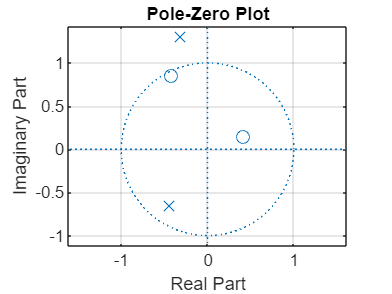

Pole-zero plot displayed.



% Plot the pole-zero diagram
plotPoleZero(poles, zerosList);

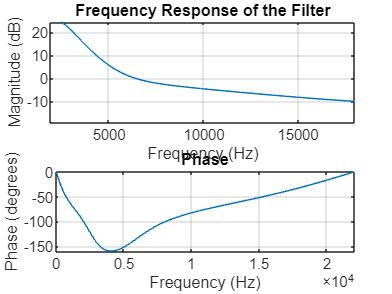

Frequency response plot displayed.



% Plot the frequency response
plotFrequencyResponse(poles, zerosList, Fs);


%% Step 3: Apply DSP Operations
disp('Applying DSP operations...');

Applying DSP operations...



% Process and play the recorded audio
processAndPlay();

Applying equalizer...
Applying echo...
Applying custom filter...
Playing processed audio...
Playback complete.



%% DSP Functions

% Plot the pole-zero diagram

function plotPoleZero(poles, zerosList)
    figure('Name', 'Pole-Zero Plot');
    zplane(zerosList, poles); % MATLAB's zplane function for pole-zero plot
    title('Pole-Zero Plot');
    xlabel('Real Part');
    ylabel('Imaginary Part');
    grid on;
    disp('Pole-zero plot displayed.');
end

% Plot the frequency response
function plotFrequencyResponse(poles, zerosList, Fs)
    % Ensure poles and zeros are column vectors
    poles = poles(:); % Convert to column vector
    zerosList = zerosList(:); % Convert to column vector
    
    % Compute filter coefficients
    [b, a] = zp2tf(zerosList, poles, 1); 
    
    % Plot the frequency response
    figure('Name', 'Frequency Response');
    freqz(b, a, 1024, Fs); % MATLAB's freqz function for frequency response
    title('Frequency Response of the Filter');
    disp('Frequency response plot displayed.');
end

% Process and play the recorded audio
function processAndPlay()
    global inputSignal Fs gainBands freqBands delayTime feedback poles zerosList;

    % Validate the sampling rate
    if isempty(Fs) || ~isscalar(Fs) || ~isfinite(Fs) || Fs <= 0
        warning('Invalid sampling rate (Fs). Setting default value of 44100 Hz.');
        Fs = 44100; % Default sampling rate
    end

    % Apply DSP operations
    processedSignal = inputSignal; % Start with the input signal

    % Apply equalizer
    disp('Applying equalizer...');
    processedSignal = equalizeAudio(processedSignal, gainBands, Fs, freqBands);

    % Apply echo
    disp('Applying echo...');
    processedSignal = applyEcho(processedSignal, Fs, delayTime, feedback);

    % Apply custom filter
    disp('Applying custom filter...');
    processedSignal = applyFilter(processedSignal, poles, zerosList);

    % Check processed signal
    if isempty(processedSignal) || all(processedSignal == 0)
        error('Processed signal is empty or silent. Check DSP functions for errors.');
    end

    % Normalize the processed signal
    processedSignal = processedSignal / max(abs(processedSignal));

    % Play the processed audio
    disp('Playing processed audio...');
    audioOut = audioplayer(processedSignal, Fs);
    playblocking(audioOut);
    disp('Playback complete.');
end

% Equalizer implementation
function output = equalizeAudio(input, gainBands, Fs, freqBands)
    output = zeros(size(input));
    for i = 1:length(freqBands)
        % Valid frequency range
        lowerCutoff = max(20, freqBands(i) * 0.8);
        upperCutoff = min(Fs / 2 - 1, freqBands(i) * 1.2);

        % Skip invalid ranges
        if lowerCutoff >= upperCutoff
            warning('Invalid filter range for band %d. Skipping...', i);
            continue;
        end

        % Design bandpass filter
        try
            bpFilter = designfilt('bandpassiir', ...
                'FilterOrder', 4, ...
                'HalfPowerFrequency1', lowerCutoff, ...
                'HalfPowerFrequency2', upperCutoff, ...
                'SampleRate', Fs);
            filteredSignal = filter(bpFilter, input);
            output = output + gainBands(i) * filteredSignal;
        catch ME
            warning('Error in filter design for band %d: %s', i, ME.message);
        end
    end
end

% Echo implementation
function output = applyEcho(input, Fs, delayTime, feedback)
    delaySamples = round(delayTime * Fs);
    if delaySamples < 1
        warning('Delay time too short. Skipping echo.');
        output = input;
        return;
    end
    buffer = zeros(delaySamples, 1);
    output = zeros(size(input));
    for n = 1:length(input)
        echoSample = buffer(1);
        output(n) = input(n) + feedback * echoSample;
        buffer = [input(n); buffer(1:end-1)];
    end
end

% Filter design implementation using poles and zeros
function output = applyFilter(input, poles, zerosList)
    if isempty(poles) && isempty(zerosList)
        output = input; % No filter applied
        return;
    end
    try
        % Compute filter coefficients from poles and zeros
        b = poly(zerosList); % Numerator coefficients
        a = poly(poles);     % Denominator coefficients

        % Apply the filter to the signal
        output = filter(b, a, input);
    catch ME
        warning('Error in custom filter: %s', ME.message);
        output = input;
    end
end
